# Classifying ECG Signals (Part 2 - LSTMs)

Make sure you complete part 1 of this exercise first.

edit Solution_ECG_CNN.mlx

## Preprocess Data using Wavelet Scattering

If we tried feeding our data directly into a deep network, it would not perform well. The signal length length is too long (65536 samples), and signal drift makes it difficult to perform classification. 

Wavelet scattering automatically extracts low-variance, compact features in a way that minimizes the differences within a class while preserving discriminability across classes. 

It will reduce the dimensionality from 65536 samples to a feature matrix with 8 channels, each with 499 features.

sampleSig = ECGData.Data(1,:);
sf = waveletScattering('SignalLength', numel(sampleSig), 'SamplingFrequency', Fs);
feat = featureMatrix(sf, sampleSig);

The variable `feat` contains the autoamtically extracted features from the signal. 

whos sampleSig

  Name           Size                Bytes  Class     Attributes

  sampleSig      1x65536            524288  double              



whos feat

  Name        Size            Bytes  Class     Attributes

  feat      492x8             31488  double              



## **Extract Features for Training and Test Set**

We will load a prepartitioned dataset that's been partitioned randomly into a training datset and a testing dataset.

load('PartitionedData.mat')

Using our existing wavelet scattering transform, compute the scatter features for the training and testing datasets.

scat_features_train = cell(113,1);
scat_features_test = cell(49,1);

parfor itr = 1:113   %113 Training Records
    tmp = featureMatrix(sf,trainData(itr,:));
    scat_features_train{itr,1} =tmp;
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.



parfor ttr = 1:49    % 49 Test Records
    % Store the featureMatrix of testData 
    tmp = featureMatrix(sf,testData(ttr,:));
    scat_features_test{ttr,1} =tmp;
end

## Create LSTM Network 

Let's now set up a very simple LSTM network to train. Retrain with different values of hidden units in the lstmLayer.  

[inputSize,~] = size(scat_features_train{1});
numClasses = 3; 
numHiddenUnits = 100; 

% Store the LSTM Network in the variable "layers"
layers = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer];

## **Train the Network**

Retrain the network. Use the following training options and save them to variable "opts"

- `InitialLearnRate 0.01`

- `MaxEpochs        125 `

- `MiniBatchSize    1000`

- `SequenceLength   'shortest'`

- `Shuffle          'never'`

- `Plots            'training-progress' `

To ensure correct operation of deep learning models, it's essential to accurately define the `input Data Format` by understanding and specifying the dimensions of your data. This can be done by using the **InputDataFormats** argument in **trainingOptions** to match the expected format. Read more about it at [Deep Learning Data Formats](https://www.mathworks.com/help/deeplearning/ug/deep-learning-data-formats.html)

`Hint : ``doc trainingOptions `

opts = trainingOptions('adam', ...
    'InitialLearnRate',0.01,...
    'MaxEpochs',125, ...
    'MiniBatchSize',1000, ...
    'SequenceLength','shortest', ...
    'Shuffle','never',...
    'Plots','training-progress', ...
    'InputDataFormats',"CTB");

Now train the network and save it to variable "ECGScatNet"

`Hint : ``doc trainnet `

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss
    _________    _____    ___________    _________    ____________
            1        1       00:00:01         0.01          1.1014
           50       50       00:00:07         0.01        0.015105
          100      100       00:00:09         0.01      0.00022969
          125      125       00:00:10         0.01       0.0003081
Training stopped: Max epochs completed


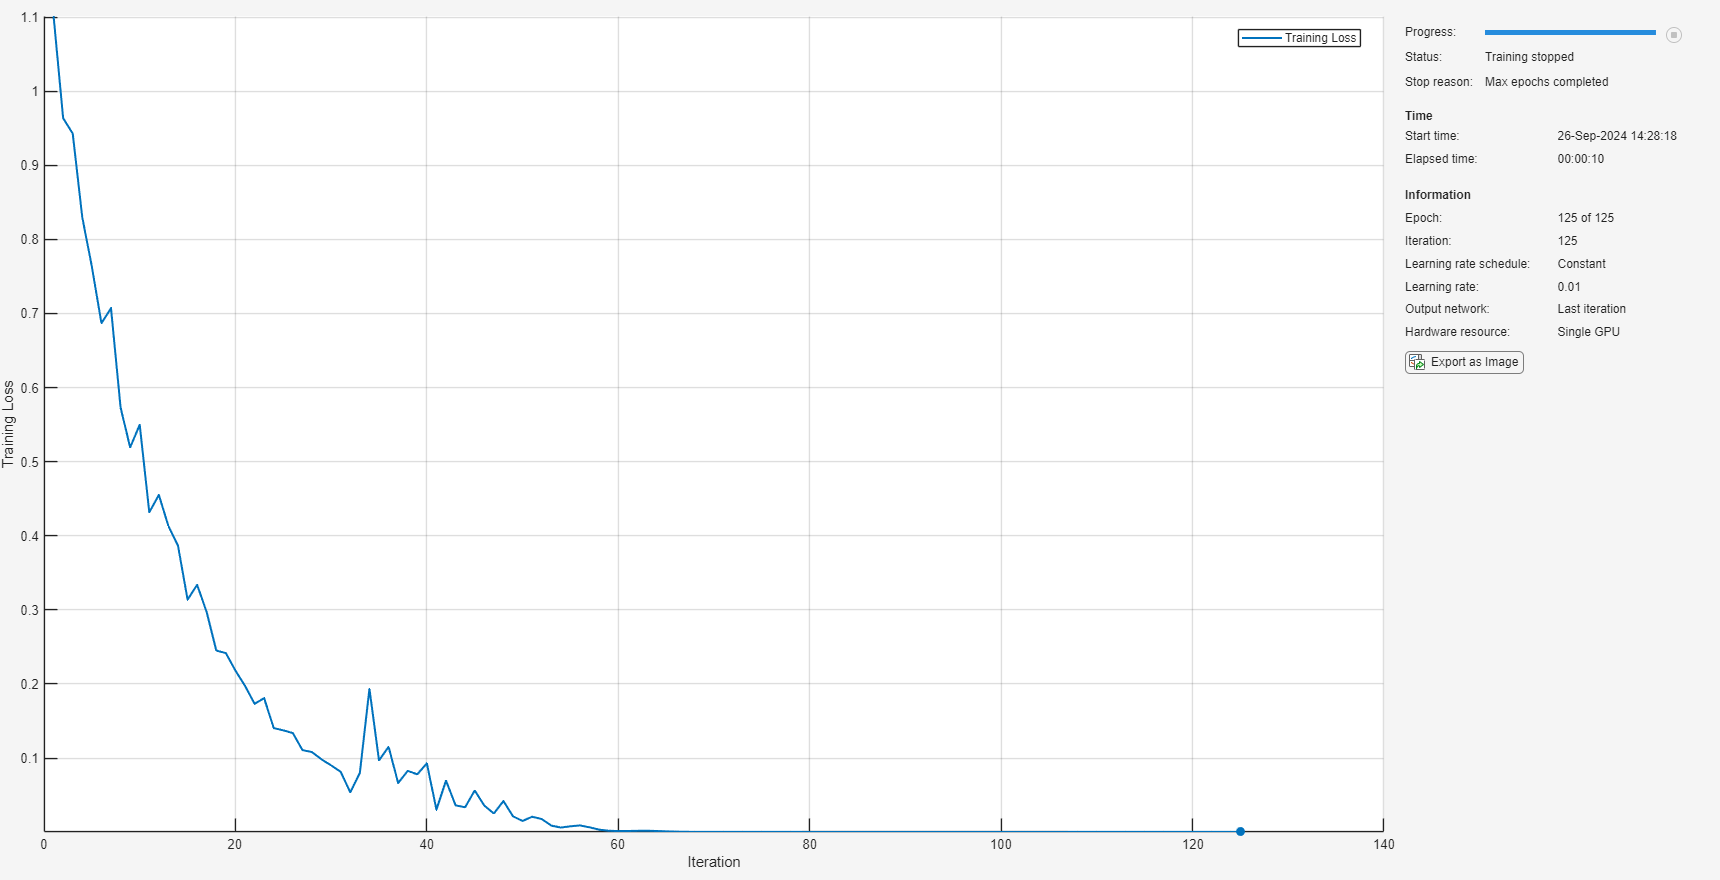

YTrain = categorical(trainLabels);
ECGScatNet = trainnet(scat_features_train, YTrain, layers, "crossentropy", opts);

## **Evaluate LSTM model **

Now we can test our fully trained model:

YTest = categorical(testLabels);

% Use the minibatchpredict function on the ECGScatNet on test data 
scores = minibatchpredict(ECGScatNet, scat_features_test, "InputDataFormats", "CTB");
classNames = categories(YTrain);
YPred = scores2label(scores, classNames);

accuracy = testnet(ECGScatNet, scat_features_test, YTest, "accuracy","InputDataFormats", "CTB")

accuracy = 89.7959

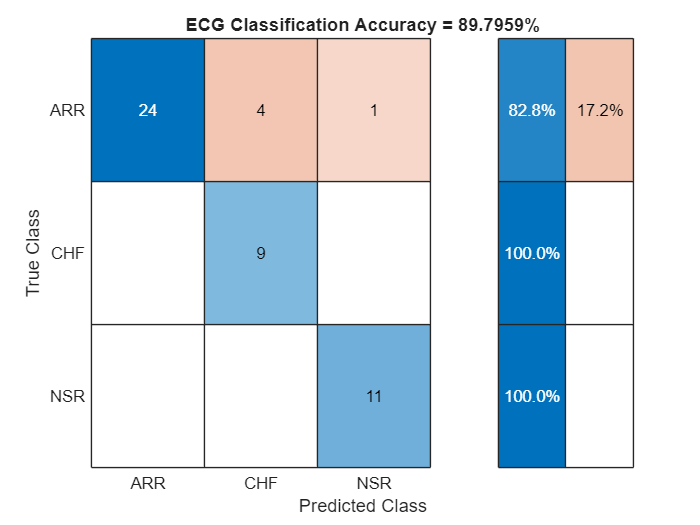


cm = confusionchart(YTest, YPred);
figure
cm.RowSummary = 'row-normalized';
cm.Title = ['ECG Classification Accuracy = ' num2str(accuracy) '%'];

## Summary

This example used wavelet time scattering and an LSTM to classify ECG waveforms into one of three diagnostic classes. Wavelet scattering proved to be a powerful feature extractor, which required only a minimal set of user-specified parameters to yield a set of robust features for classification. 

*Copyright 2024 The MathWorks, Inc.*